%data = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/Features_v1.csv', 'ReadVariableNames',1);
data = readtable('Datasets/Features_v1.csv', 'ReadVariableNames',1);

GD = data.GoodDays; 
MD = data.ModerateDays;
UFSGD = data.UnhealthyForSensitiveGroupsDays;
UD = data.UnhealthyDays;
VUD = data.VeryUnhealthyDays;
HD = data.HazardousDays;

RD = [GD MD UFSGD UD VUD HD];
edges = [0:0.025:1];
edgesN = [-1:0.05:1];

%GD 
minGD = min(GD)

minGD = 0.1004

maxGD = max(GD)

maxGD = 0.9986

nnzGD = nnz(GD)

nnzGD = 832

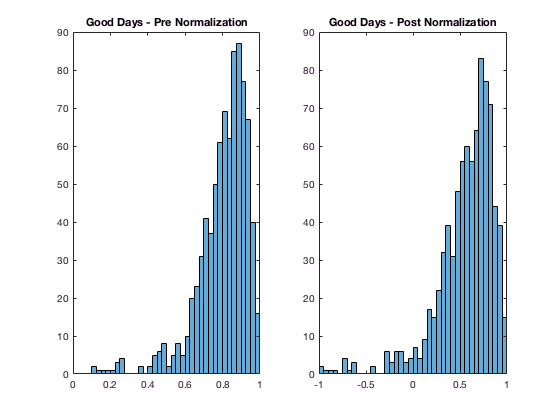


figure(1)
subplot(1,2,1)
histogram(GD, edges)
title('Good Days - Pre Normalization')

GDN = 2*((GD-minGD)/(maxGD-minGD))-1;
subplot(1,2,2)
histogram(GDN, edgesN)
ylim([0 90])
title('Good Days - Post Normalization')

%MD 
minMD = min(MD)

minMD = 0.0014

maxMD = max(MD)

maxMD = 0.7120

nnzMD = nnz(MD) 

nnzMD = 832

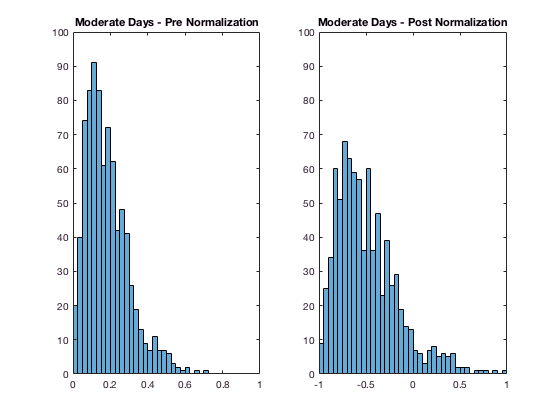


figure(2)
subplot(1,2,1)
histogram(MD, edges)
title('Moderate Days - Pre Normalization')

MDN = 2*((MD-minMD)/(maxMD-minMD))-1;
subplot(1,2,2)
histogram(MDN, edgesN)
ylim([0 100])
title('Moderate Days - Post Normalization')

%UFSGD
minUFSGD = min(UFSGD)

minUFSGD = 0

maxUFSGD = max(UFSGD)

maxUFSGD = 0.2822

nnzUFSGD = nnz(UFSGD)

nnzUFSGD = 756


figure(3)
subplot(1,2,1)
histogram(UFSGD, edges)
ylim([0 800])
title('Unhealthy for Sensitive Groups - Pre Normalization')

UFSGDN = log((UFSGD+0.01));

minUFSGDN = min(UFSGDN)

minUFSGDN = -4.6052

maxUFSGDN = max(UFSGDN)

maxUFSGDN = -1.2303

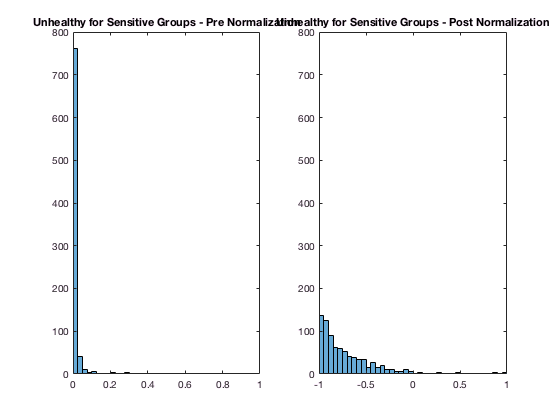


UFSGDN = 2*((UFSGDN-minUFSGDN)/(maxUFSGDN-minUFSGDN))-1;
subplot(1,2,2)
histogram(UFSGDN, edgesN)
ylim([0 800])
title('Unhealthy for Sensitive Groups - Post Normalization')

%UD
minUD = min(UD)

minUD = 0

maxUD = max(UD)

maxUD = 0.3305

nnzUD = nnz(UD)

nnzUD = 351

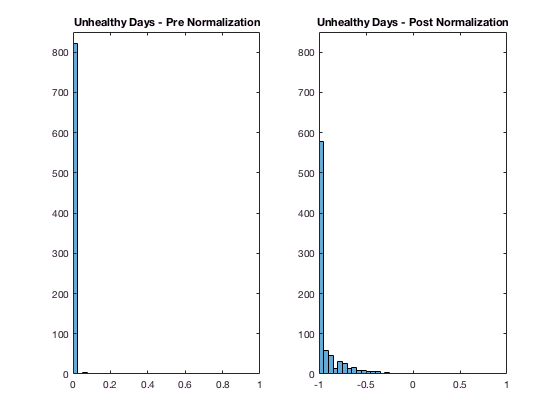


figure(4)
subplot(1,2,1)
histogram(UD, edges)
title('Unhealthy Days - Pre Normalization')
ylim([0 850])

UDN = log(UD+0.005);
minUDN = min(UDN);
maxUDN = max(UDN);

UDN = 2*((UDN-minUDN)/(maxUDN-minUDN))-1;

subplot(1,2,2)
histogram(UDN,edgesN)
ylim([0 850])
title('Unhealthy Days - Post Normalization')

%VUD
% minVUD = min(VUD)
% maxVUD = max(VUD)
% nnzVUD = nnz(VUD)
% 
% figure(5)
% subplot(1,2,1)
% histogram(VUD, edges)
% ylim([0 850])
% title('Very Unhealthy Days - Pre Normalization')
% 
% nnzVUD_V = VUD(VUD~=0);
% medVUD_V = median(nnzVUD_V);
% 
% % t = 100*VUD
% % tt = t(t~=0)
% % sort(t, 'descend')
% % ttt = tanh(5*(tt-0.35)); 
% % histogram(ttt, edgesN)
% 
% VUDN = tanh(1500*(VUD-0.001));
% minVUDN = min(VUDN);
% maxVUDN = max(VUDN);
% 
% VUDN = 2*((VUDN-minVUDN)/(maxVUDN-minVUDN))-1;
% subplot(1,2,2)
% histogram(VUDN,edgesN)
% ylim([0 850])
% title('Very Unhealthy Days - Post Normalization')

%HD
% minHD = min(HD)
% maxHD = max(HD)
% nnzHD = nnz(HD)
% 
% figure(6)
% subplot(1,2,1)
% histogram(HD, edges)
% ylim([0 850])
% title('Hazardous Days - Pre Normalization')
% 
% nnzHD_V = HD(HD~=0);
% medHD_V = median(nnzHD_V);
% 
% HDN = tanh(3000*(HD-0.0005));
% minHDN = min(HDN);
% maxHDN = max(HDN);
% 
% HDN = 2*((HDN-minHDN)/(maxHDN-minHDN))-1;
% subplot(1,2,2)
% histogram(HDN, edgesN)
% ylim([0 850])
% title('Hazardous Days - Post Normalization')

NormMat = [GDN MDN UFSGDN UDN];

[t_RND, C_RND] = kmeans(NormMat, 3)

t_RND =      1
     1
     1
     2
     1
     3
     1
     2
     2
     1


C_RND =     0.7578   -0.7049   -0.8526   -0.9601
    0.4067   -0.2852   -0.6120   -0.9052
   -0.2263    0.2555    0.1455   -0.4852


RND_kC1 = RD(t_RND ==1,:);
RND_kC2 = RD(t_RND ==2,:);
RND_kC3 = RD(t_RND ==3,:);
%RND_kC4 = RD(t_RND ==4,:);

extreme_values = VUD + HD;

extreme_values =    1.0e-03 *

         0
         0
         0
         0
         0
         0
         0
         0
    0.4817
         0


extreme_values = extreme_values ~=0;

extreme_values = 832×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   1
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   1
   0
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   0
   1
   0
   1
   0
   0
   1
   1
   1
   0
   1
   0
   1
   1
   0
   0
   1
   0
   0
   0
   0
   1
   1
   1
   1
   0
   1
   0
   1
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   1
   0
   0
   0
   1
   0
   0
   0
   0
   0
   1
   1
   0
   0
   0
   1
   0
   0
   0
   0
   0
   

ndata = data(:,[1,2,3,10,11,12]);
ndata.AQI_Class_KM = t_RND;
ndata.Extreme_AQI = extreme_values;
writetable(ndata, 'Datasets/AQI_Features.csv')
%writetable(ndata, '/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/AQI_Features.csv')
ver = data(:,[1:9]);
ver.Class = t_RND;
writetable(ver, 'Datasets/AQI_Class_Comparison.csv')